#### Test Case 1: 13 Cambridge Communities - Trapezoidal

clear; close all;

t_start = 0;
t_stop = 100;
rng(5);


% test FE function
[X] = trapezoidal();

%% Convert SEIR cell time series to matrix
for i = 1:size(X,2)
    
    trapState(:,i) = convertSeirCellToMat(X(:,i));
    
end

%% Plot SEIR curves for each node
for i = 1:size(X,1)
    
    State = X(i,:);
    state = [State{1:end}];
    
    N(i,:) = sum(state, 1);
    
    figure(i);
    hold on;
    days = linspace(t_start,t_stop,length(state(1,1:end)));
    plot(days, state(1,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, state(2,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, state(3,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, state(4,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    hold off;
    legend('S(t)','E(t)','I(t)','R(t)');
    title(['Test Case 1' ' Node ', num2str(i)])
    
    if i == 1
        sumState = state;     
    else
        sumState = sumState + state;     
    end
end

figure;
hold on;
days = linspace(t_start,t_stop,length(sumState(1,1:end)));
plot(days, sumState(1,1:end),  'LineWidth', 1.5);
xlabel('t [days]');

plot(days, sumState(2,1:end),  'LineWidth', 1.5);
xlabel('t [days]');

plot(days, sumState(3,1:end), 'LineWidth', 1.5);
xlabel('t [days]');

plot(days, sumState(4,1:end), 'LineWidth', 1.5);
xlabel('t [days]');
hold off;
legend('S(t)','E(t)','I(t)','R(t)');
title('Test Case 1 All Nodes')

figure;
imagesc(N(:,:));
title('Test Case 1 N(t)');
xlabel('Timestep');
ylabel('Node');
colorbar;

save('techChallengeStats.mat', 'trapState', '-append');

#### Test Case 2: 13 Cambridge Communities - Forward Euler 

clear; close all;

rng(5);

t_start = 0;
t_stop = 100;
timestep = 0.1;

%select input evaluation function
eval_u = 'GenInputVec';

%select model evaluation function
eval_f = 'EVALF';

[P, x_start, p, u] = initializeCambridgeCommunities();

% test FE function
[X] = ForwardEuler(P, eval_f, x_start, p, eval_u, t_start, t_stop, timestep);

%% Convert SEIR cell time series to matrix
for i = 1:size(X,2)
    
    feState(:,i) = convertSeirCellToMat(X(:,i));
    
end

% Plot SEIR curves for each node
for i = 1:size(X,1)
    State = X(i,:);
    state = [State{1:end}];
    N(i,:) = sum(state, 1);
    figure(i);
    hold on;
    days = linspace(t_start,t_stop,length(state(1,1:end)));
    plot(days, state(1,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, state(2,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, state(3,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, state(4,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    hold off;
    legend('S(t)','E(t)','I(t)','R(t)');
    title(['Test Case 2' ' Node ', num2str(i)])
    
    if i == 1
        sumState = state;     
    else
        sumState = sumState + state;     
    end
    
end

figure;
hold on;
days = linspace(t_start,t_stop,length(sumState(1,1:end)));
plot(days, sumState(1,1:end),  'LineWidth', 1.5);
xlabel('t [days]');

plot(days, sumState(2,1:end),  'LineWidth', 1.5);
xlabel('t [days]');

plot(days, sumState(3,1:end), 'LineWidth', 1.5);
xlabel('t [days]');

plot(days, sumState(4,1:end), 'LineWidth', 1.5);
xlabel('t [days]');
hold off;
legend('S(t)','E(t)','I(t)','R(t)');
title('Test Case 2 All Nodes')

figure;
imagesc(N(:,:));
title('Test Case 2 N(t)');
xlabel('Timestep');
ylabel('Node');
colorbar;

save('techChallengeStats.mat', 'feState', '-append');

#### Error Plot

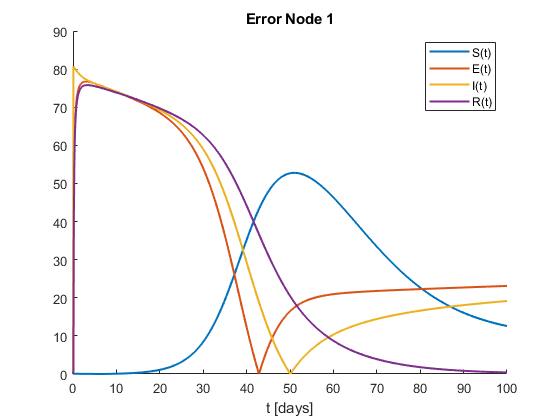

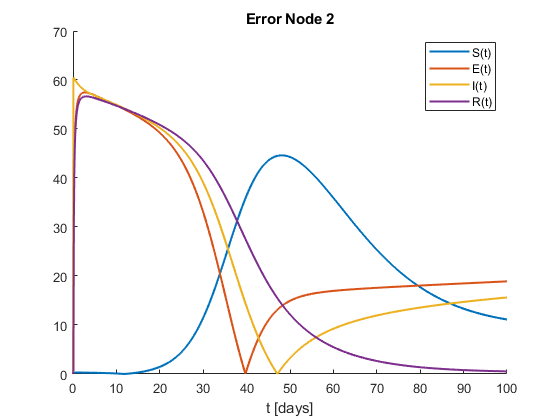

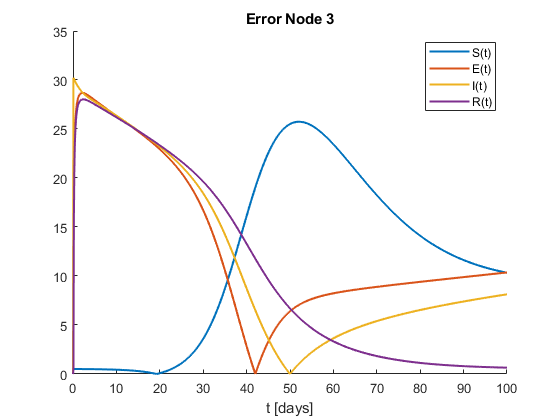

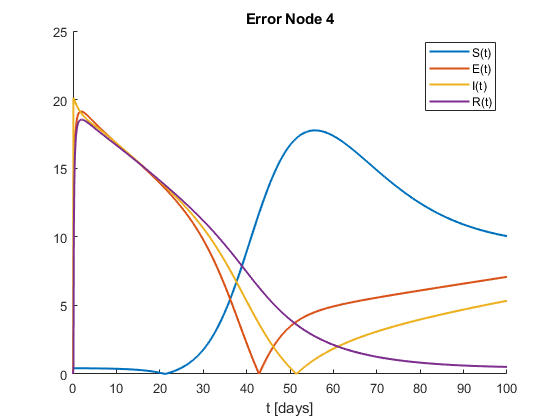

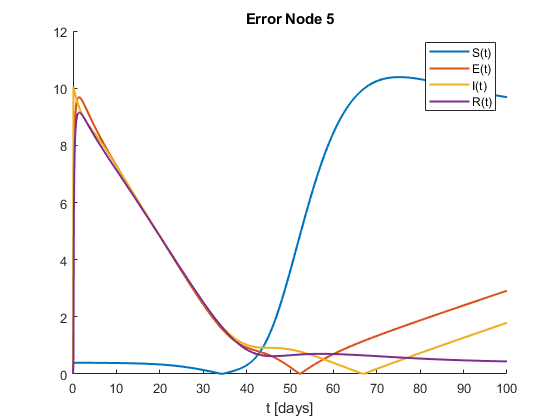

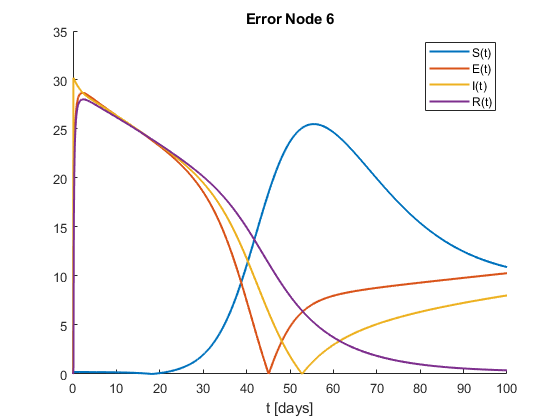

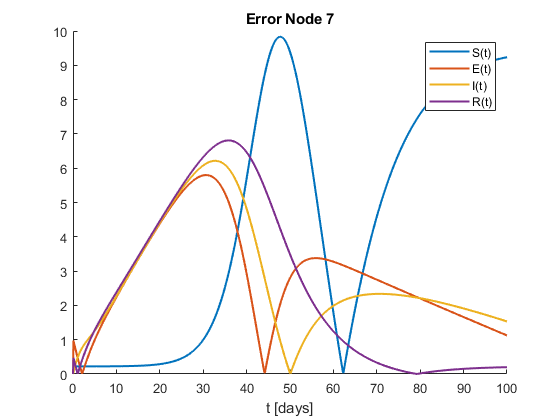

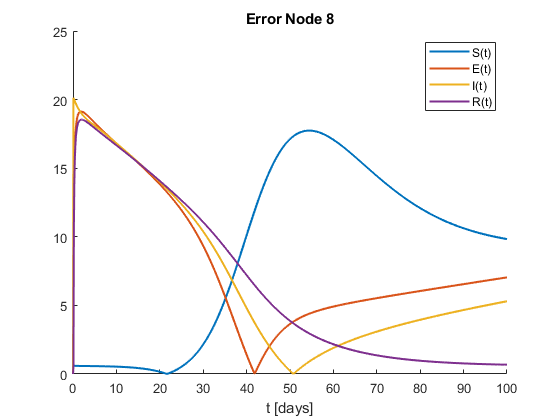

clear; close all;

load('techChallengeStats.mat');

P = 13;
c = zeros(4, P*4);

for i=1:P
    
    c(1, (i-1)*4 + 1) = 1;
    c(2, (i-1)*4 + 2) = 1;
    c(3, (i-1)*4 + 3) = 1;
    c(4, (i-1)*4 + 4) = 1;
    
end

t_start = 0;
t_stop = 100;
rng(5);

% Calculate |feState - trapState|/|trapState|*100%
errorState = abs(feState - trapState)./trapState*100;

% Assign 0% for the initial stage to avoid NaN from division by 0
errorState(:,1) = zeros(52, 1);

%Sum Error
sumTrapState = c * feState;
sumFeState = c * trapState;
sumErrorState = abs(sumFeState - sumTrapState)./sumTrapState*100;

%% Convert SEIR matrix time series to cell
for i = 1:size(errorState,2)
    errorStateCell(:,i) = convertSeirMatToCell(errorState(:,i));
end

% Plot SEIR error curves for each node
for i = 1:size(errorStateCell,1)
    State = errorStateCell(i,:);
    state = [State{1:end}];
    N(i,:) = sum(state, 1);
    
    figure(i);
    hold on;
    days = linspace(t_start,t_stop,length(state(1,1:end)));
    plot(days, state(1,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, state(2,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, state(3,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, state(4,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    hold off;
    
    legend('S(t)','E(t)','I(t)','R(t)');
    title(['Error' ' Node ', num2str(i)])
    
end

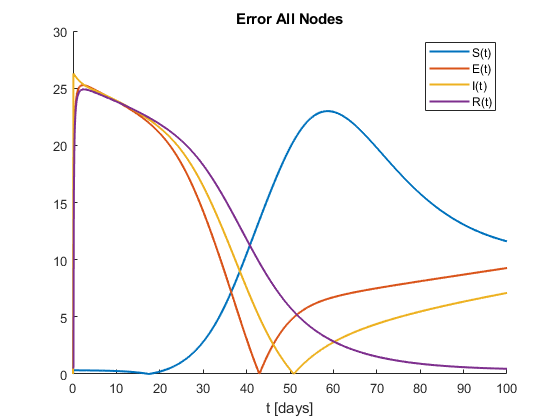



figure;
hold on;
days = linspace(t_start,t_stop,length(sumErrorState(1,1:end)));
plot(days, sumErrorState(1,1:end),  'LineWidth', 1.5);
xlabel('t [days]');

plot(days, sumErrorState(2,1:end),  'LineWidth', 1.5);
xlabel('t [days]');

plot(days, sumErrorState(3,1:end), 'LineWidth', 1.5);
xlabel('t [days]');

plot(days, sumErrorState(4,1:end), 'LineWidth', 1.5);
xlabel('t [days]');
hold off;
legend('S(t)','E(t)','I(t)','R(t)');
title('Error All Nodes')